clc; clear; % up command window and workspace
% Ruogu Fang
clc;
t0 = 1000;
tf = 10000;
a = 1000;
q = ECG_import("patient104_raw.csv",[t0,t0+tf]);
rind = ECG_FindR(q.i(a:a+1000))+a; 
pind = ECG_FindR(q.ii(a:a+1000),'p')+a;
x = ECG_filtsig(q.vx,rind); 
y = ECG_filtsig(q.vy,rind);
z = ECG_filtsig(q.vx,rind);
x = smoothdata(x,"movmean","SmoothingFactor",0.25);
y = smoothdata(y,"movmean","SmoothingFactor",0.25);
z = smoothdata(z,"movmean","SmoothingFactor",0.25);


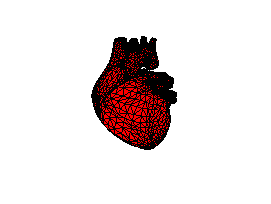


% Create 3D heart function
step = 0.05;
[X,Y,Z] = meshgrid(-3:step:3, -3:step:3, -3:step:3);
F = (-(X.^2).*(Z.^3)-(9/80).*(Y.^2).*(Z.^3))+((X.^2)+(9/4).*(Y.^2)+(Z.^2)-1).^3;
% Visualize in shaded surface
subplot(2,1,1);
demo_dynamics_wholeheart;

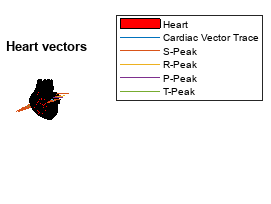

%everything above creats the 3D heart and is from the homwork. 
%to work you have to use the 3D heart provided by the class called
subplot(2,1,2);
demo_dynamics_wholeheart;
hold on % allows the graph to but laced on the heart 

plot([10,10,10], [10,10,10]); % change the vectors here. try if statment
title('Heart vectors') 
xlim([-20 20]);
ylim([-20 20]);
zlim([-20,20]); % sets graph on screen properly


tind = ECG_FindR(q.ii(a:a+1000),'t')+a;
sind = ECG_FindR(q.v2(a:a+1000),'s')+a; % Sets the parameters for finding the R,P,T, and S waves
plot3(x(a:a+1000)*80,y(a:a+1000)*80,z(a:a+1000)*80);
hold on
plot3([0,x(sind)*80],[0,y(sind)*80],[0,z(sind)*80]);
plot3([0,x(rind)*80],[0,y(rind)*80],[0,z(rind)*80]);
plot3([0,x(pind)*80],[0,y(pind)*80],[0,z(pind)*80]);
plot3([0,x(tind)*80],[0,y(tind)*80],[0,z(tind)*80]); % plots the waves on top of the 3d heart
hold off 
zlim([-20,20]);
xlim([-20,20]);
ylim([-20,20]);  %sets the limits on the heart. screw around with the numbers to creat the 2D representation
legend('Heart','Cardiac Vector Trace','S-Peak','R-Peak','P-Peak','T-Peak');